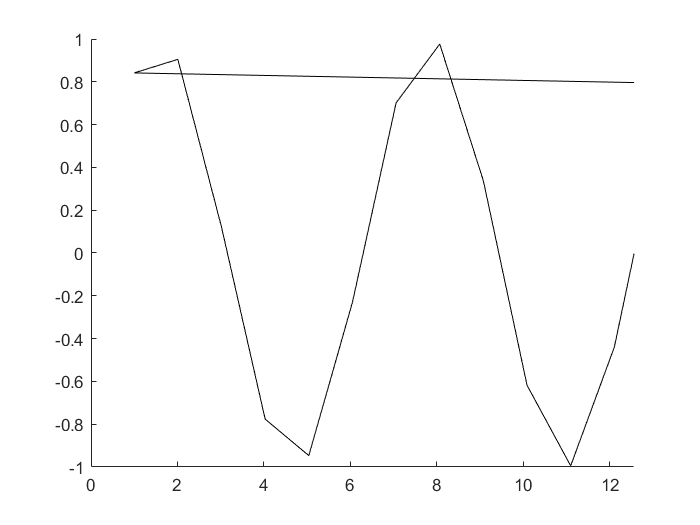

% ********************************************************************************************************************
% ********************************************************************************************************************
close all
clear

ctxt.tcpHandle = [];
ctxt.aline = animatedline;
ctxt.x = [];
ctxt.cnt = 1;
axis([0 4*pi -1 1])



add_no={'Address'};
default={'192.168.3.83'};
inputIP=inputdlg(add_no,'Input Address',[1 30;],default);

%连接远程服务器，端口号3338。
if(~isempty(inputIP))
    ctxt.tcpHandle = tcpclient(char(inputIP), 3338);
end

if(~isempty(ctxt.tcpHandle))
    readCmd=uint8([hex2dec('55') , hex2dec('05') , hex2dec('03') , hex2dec('06') , hex2dec('00') , hex2dec('00') , hex2dec('00') , hex2dec('0A')]);
    write(ctxt.tcpHandle,readCmd,"uint8");
 %   rdStr = read(ctxt.tcpHandle);
    FreshTimer = timer(...
        'ExecutionMode', 'fixedRate', ...    % Run timer repeatedly
        'Period', 1, ...                     % Period is 1 second
        'BusyMode', 'queue',...              % Queue timer callbacks when busy
        'TimerFcn', @FreshTimerFcn);      % Specify callback function
FreshTimer.UserData = ctxt;
start(FreshTimer);
end

function FreshTimerFcn(mTimer,~)

if(~isempty(mTimer.UserData))
     RecData = read(mTimer.UserData.tcpHandle);
    if(~isempty(RecData))
        disp(RecData);
        mTimer.UserData.x = linspace(0,4*pi,2000);
        mTimer.UserData.cnt = 1;

    end

 %   if (mTimer.UserData.cnt < 2000)
        mTimer.UserData.x = linspace(mTimer.UserData.cnt,mTimer.UserData.cnt+100,100);
        y = sin(mTimer.UserData.x);
        addpoints(mTimer.UserData.aline,mTimer.UserData.x,y);
        drawnow 
        mTimer.UserData.cnt = mTimer.UserData.cnt+100;
%    end
end

end